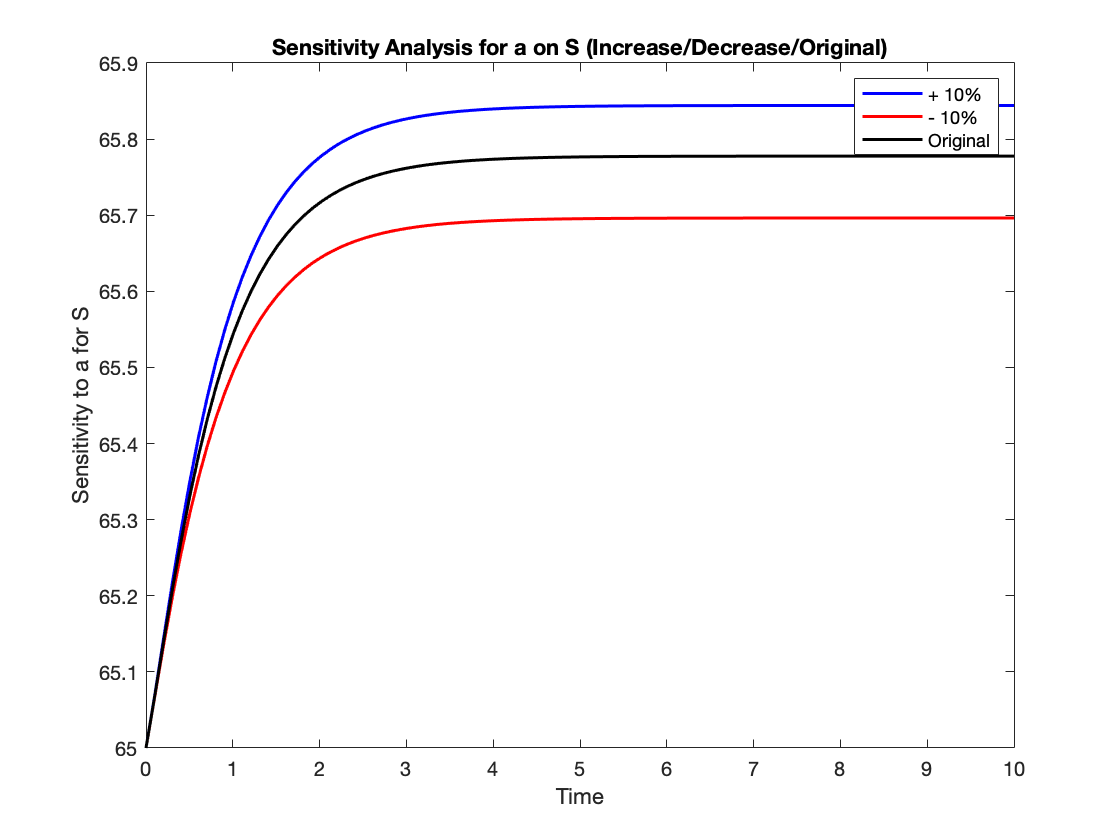

Sensitivity Coefficient for a (Increase): 1.5841


Parameter Ranking for a (Increase): 6


Sensitivity Coefficient for a (Decrease): 1.9360


Parameter Ranking for a (Decrease): 4


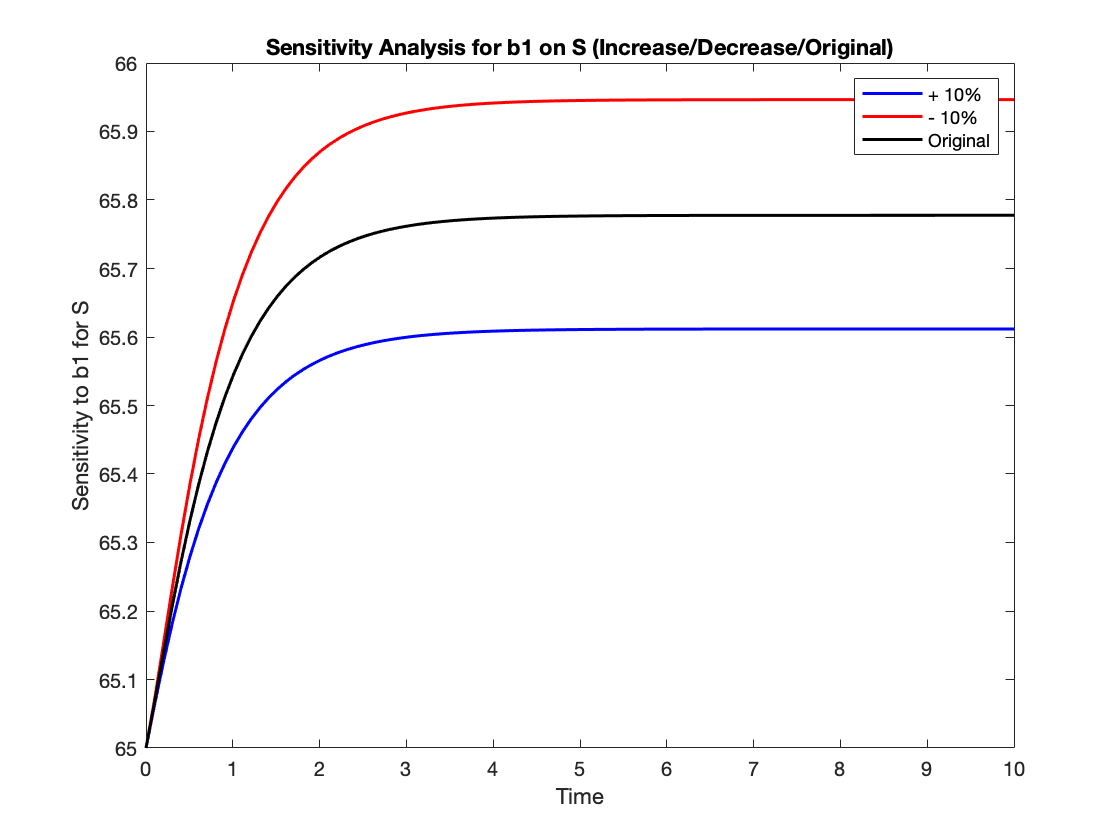

Sensitivity Coefficient for b1 (Increase): -2.3707


Parameter Ranking for b1 (Increase): 3


Sensitivity Coefficient for b1 (Decrease): -2.4123


Parameter Ranking for b1 (Decrease): 3


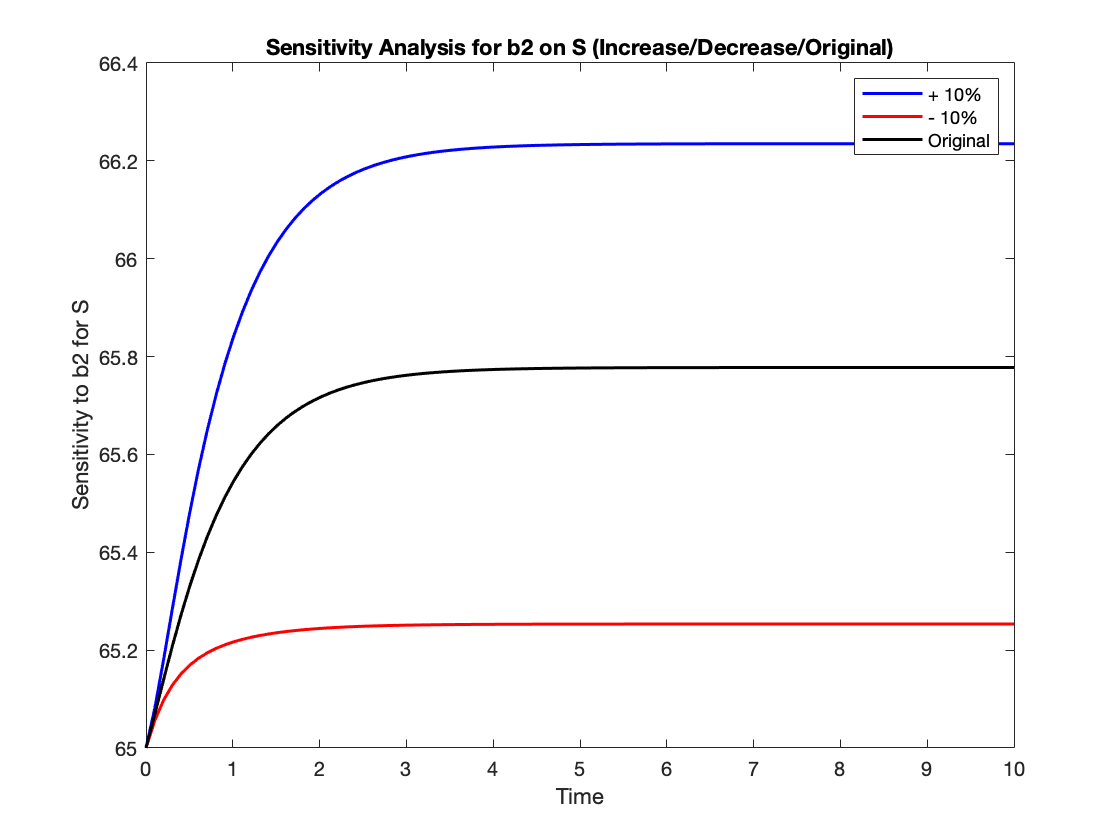

Sensitivity Coefficient for b2 (Increase): 1.5938


Parameter Ranking for b2 (Increase): 5


Sensitivity Coefficient for b2 (Decrease): 1.8267


Parameter Ranking for b2 (Decrease): 5


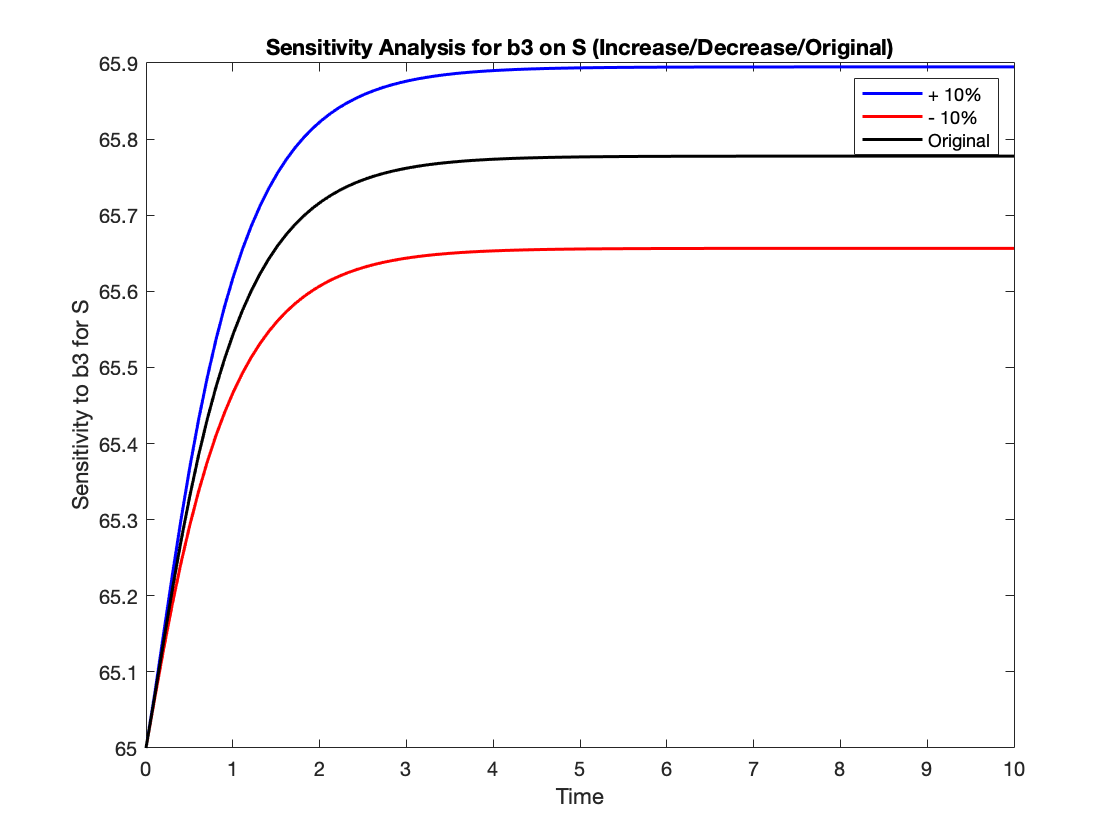

Sensitivity Coefficient for b3 (Increase): 1.6746


Parameter Ranking for b3 (Increase): 4


Sensitivity Coefficient for b3 (Decrease): 1.7311


Parameter Ranking for b3 (Decrease): 6


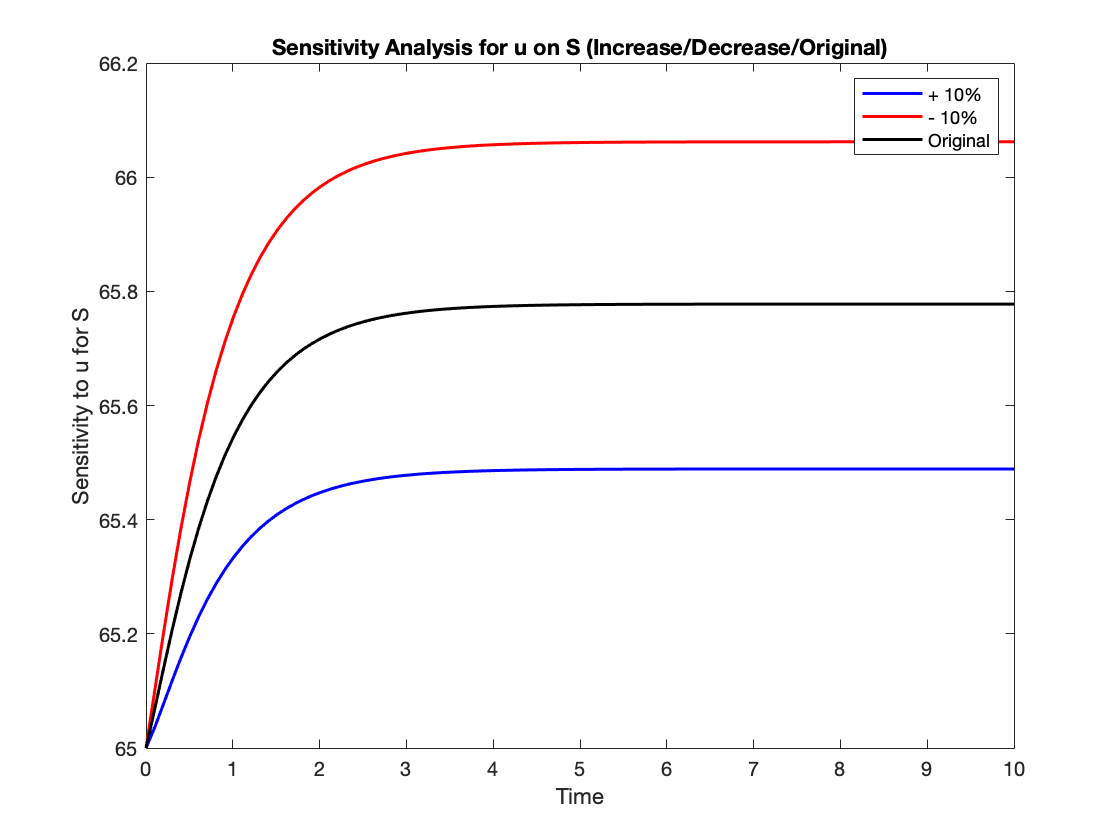

Sensitivity Coefficient for u (Increase): -4.3764


Parameter Ranking for u (Increase): 2


Sensitivity Coefficient for u (Decrease): -4.3076


Parameter Ranking for u (Decrease): 2


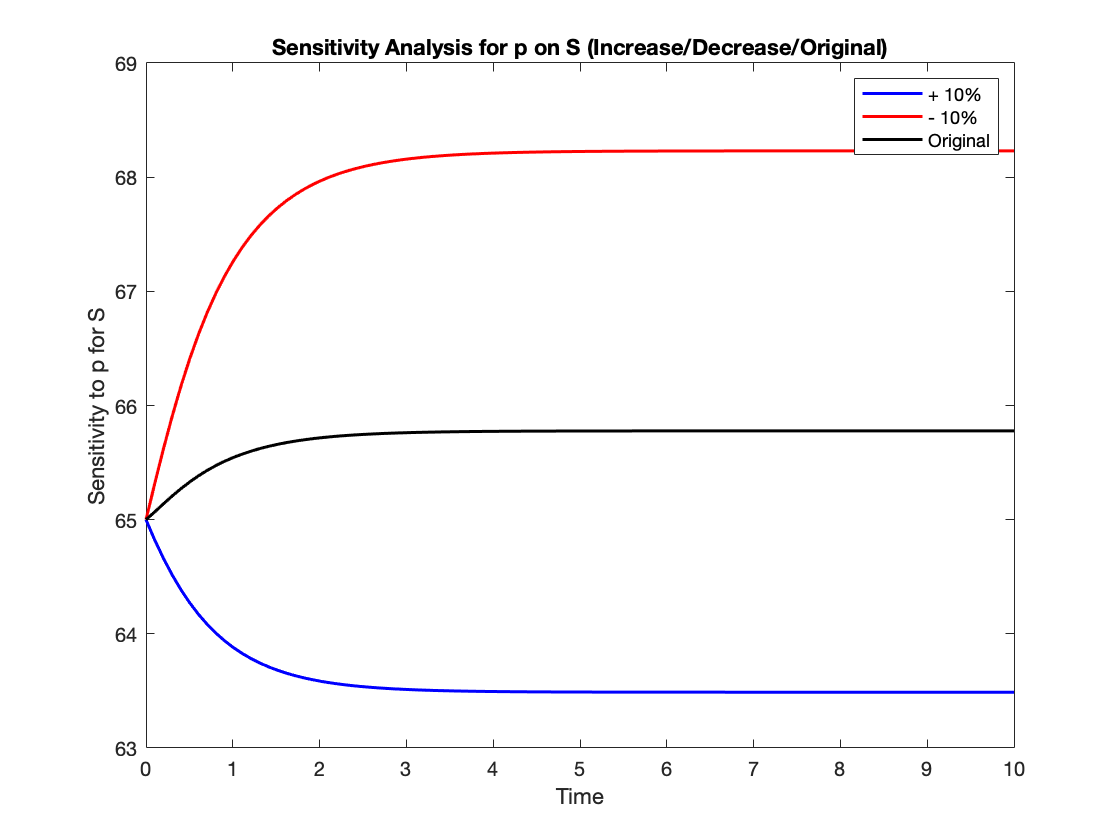

Sensitivity Coefficient for p (Increase): -59.3629


Parameter Ranking for p (Increase): 1


Sensitivity Coefficient for p (Decrease): -63.6102


Parameter Ranking for p (Decrease): 1


% SensitivityAnalysisScript

% Define time span
tspan = [0 10];  % Time span from 0 to 10

% Initial conditions
y0 = [65; 0; 7; 5; 19; 5; 1];  % Initial values of the state variables [y1, y2]

% Sensitivity analysis parameters
%DOH endemic
param_values = [0.42, 0.7, 2.87, 0.7, 0.66, 0.38558];  % Initial parameter values [a, b]
%DOH Non endemic
%param_values = [0.42, 0.04615, 2.87, 0.026275, 0.66, 0.71];
% WHO
%param_values = [0.42, 0.6655, 0.72, 0.385025, 0.66, 0.38558];
param_names = {'a', 'b1', 'b2', 'b3', 'u', 'p'};  % Parameter names for plotting

% Create a cell array to store sensitivity results for each parameter
sensitivity_results = cell(length(param_values), 6); % Six columns: increase, decrease, original for sensitivity and ranking

% Common time vector for interpolation
common_t = linspace(tspan(1), tspan(2), 100); % Adjust the number of points as needed

% Sensitivity coefficients and parameter rankings
sensitivity_coefficients_increase = zeros(length(param_values), 1);
sensitivity_coefficients_decrease = zeros(length(param_values), 1);
parameter_ranking_increase = zeros(length(param_values), 1);
parameter_ranking_decrease = zeros(length(param_values), 1);

% Perform sensitivity analysis for both increase and decrease
for i = 1:length(param_values)
    params = param_values;
    
    % Perturb one parameter at a time (10% increase)
    perturbation = 0.1;  % Adjust the size of the perturbation as needed
    params_increase = params;
    params_increase(i) = params(i) * (1 + perturbation);
    
    % Solve the ODE system with the perturbed parameter (increase)
    [t_increase, y_increase] = ode45(@(t, y) ode_model_function(t, y, params_increase), tspan, y0);
    
    % Interpolate the sensitivity results to the common time vector (increase)
    sensitivity_results{i, 1} = interp1(t_increase, y_increase(:, 1), common_t, 'linear', 'extrap');
    
    % Perturb one parameter at a time (10% decrease)
    params_decrease = params;
    params_decrease(i) = params(i) * (1 - perturbation);
    
    % Solve the ODE system with the perturbed parameter (decrease)
    [t_decrease, y_decrease] = ode45(@(t, y) ode_model_function(t, y, params_decrease), tspan, y0);
    
    % Interpolate the sensitivity results to the common time vector (decrease)
    sensitivity_results{i, 2} = interp1(t_decrease, y_decrease(:, 1), common_t, 'linear', 'extrap');
    
    % Solve the ODE system with the original parameter
    [t_original, y_original] = ode45(@(t, y) ode_model_function(t, y, params), tspan, y0);
    
    % Interpolate the sensitivity results to the common time vector (original)
    sensitivity_results{i, 3} = interp1(t_original, y_original(:, 1), common_t, 'linear', 'extrap');
    
    % Calculate sensitivity coefficients for increase and decrease
    delta_param = params(i) * perturbation;
    delta_y_increase = sensitivity_results{i, 1} - sensitivity_results{i, 3};
    delta_y_decrease = sensitivity_results{i, 3} - sensitivity_results{i, 2};
    
    sensitivity_coefficients_increase(i) = delta_y_increase(end) / delta_param;
    sensitivity_coefficients_decrease(i) = delta_y_decrease(end) / delta_param;
    
    % Parameter ranking for increase and decrease
    [~, ranking_index_increase] = sort(abs(sensitivity_coefficients_increase), 'descend');
    [~, ranking_index_decrease] = sort(abs(sensitivity_coefficients_decrease), 'descend');
    
    parameter_ranking_increase(ranking_index_increase) = 1:length(param_values);
    parameter_ranking_decrease(ranking_index_decrease) = 1:length(param_values);
end

% Plot sensitivity analysis results for each parameter (increase and decrease)
for i = 1:length(param_values)
    figure;
    plot(common_t, sensitivity_results{i, 1}, 'b', 'LineWidth', 1.5);
    hold on;
    plot(common_t, sensitivity_results{i, 2}, 'r', 'LineWidth', 1.5);
    plot(common_t, sensitivity_results{i, 3}, 'k', 'LineWidth', 1.5);
    xlabel('Time');
    ylabel(['Sensitivity to ', param_names{i}, ' for S']); %change S
    title(['Sensitivity Analysis for ', param_names{i}, ' on S (Increase/Decrease/Original)']); %Change S to corresponding state variable
    legend('+ 10%', '- 10%', 'Original');
    
    % Display sensitivity coefficients and parameter rankings for increase and decrease
    fprintf('Sensitivity Coefficient for %s (Increase): %.4f\n', param_names{i}, sensitivity_coefficients_increase(i));
    fprintf('Parameter Ranking for %s (Increase): %d\n', param_names{i}, parameter_ranking_increase(i));
    
    fprintf('Sensitivity Coefficient for %s (Decrease): %.4f\n', param_names{i}, sensitivity_coefficients_decrease(i));
    fprintf('Parameter Ranking for %s (Decrease): %d\n', param_names{i}, parameter_ranking_decrease(i));
end

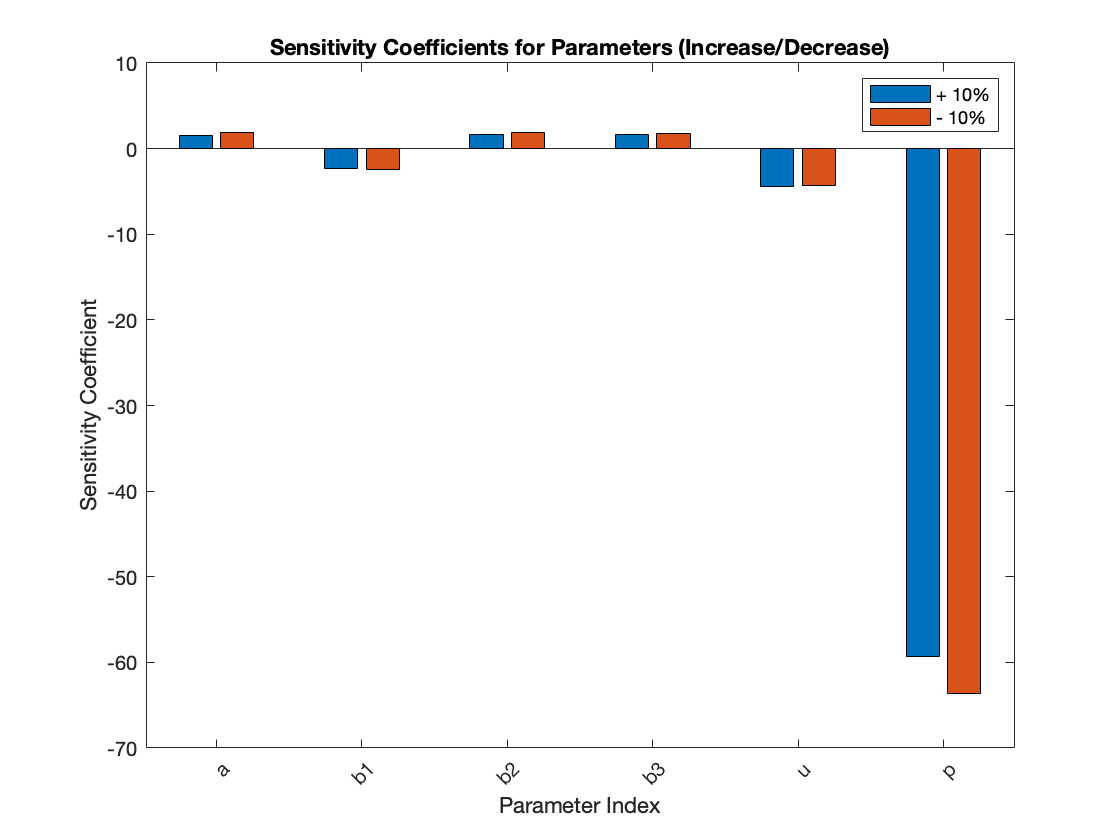


% Create a single histogram for sensitivity coefficients (increase and decrease)
figure;
bar([sensitivity_coefficients_increase, sensitivity_coefficients_decrease], 'grouped');
xlabel('Parameter Index');
ylabel('Sensitivity Coefficient');
title('Sensitivity Coefficients for Parameters (Increase/Decrease)');
legend('+ 10%', '- 10%');

% Add parameter names as labels to the bars
xticklabels(param_names);
xtickangle(45); % Rotate labels for readability